# Trabajo práctico: Control en el espacio de estados

##  Ej 1

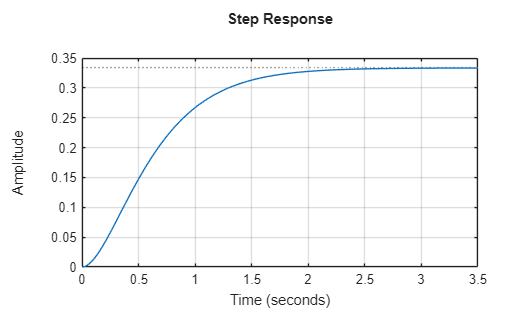

zeta_A = 1;
zeta_B = 0.6;
omega_A = 3;
omega_B = 1/zeta_B;
G_A = tf(omega_A, [1 2*zeta_A*omega_A omega_A^2]);
step(G_A)
grid on

stepinfo(G_A)

ans = struct with fields:
         RiseTime: 1.1194
    TransientTime: 1.9447
     SettlingTime: 1.9447
      SettlingMin: 0.3006
      SettlingMax: 0.3333
        Overshoot: 0
       Undershoot: 0
             Peak: 0.3333
         PeakTime: 3.9758


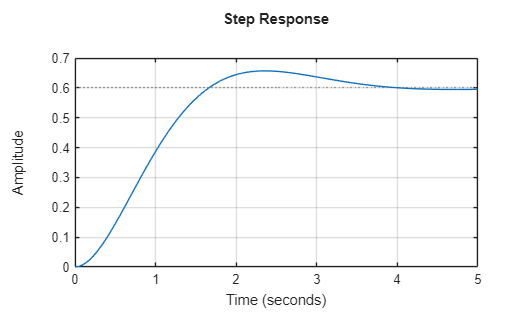

G_B = tf(omega_B, [1 2*zeta_B*omega_B omega_B^2]);
step(G_B)
grid on

stepinfo(G_B)

ans = struct with fields:
         RiseTime: 1.1134
    TransientTime: 3.5661
     SettlingTime: 3.5661
      SettlingMin: 0.5450
      SettlingMax: 0.6569
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 0.6569
         PeakTime: 2.3486


### Ej 2

Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 7500;
i  = 57;

A = [ -ds/(Jf*i^2),   ds/(Jf*i),   -cs/(Jf*i);
       ds/(Jc*i),    -ds/Jc,        cs/Jc;
       1/i,          -1,            0 ];

B_u = [ 1/Jf;
      0;
      0 ];

B_d = [ 0;
     -1/Jc;
      0 ];

C = [0 1 0];

D = 0;

wn = 6;
zeta = 1/sqrt(2);

p1 = -zeta*wn + 1j*wn*sqrt(1-zeta^2)'
p2 = -zeta*wn - 1j*wn*sqrt(1-zeta^2)'
p3 = -2*zeta*wn;

p_deseados = [p1 p2 p3];
K = acker(A, B, p_deseados);
